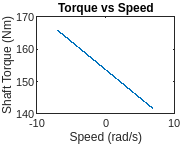

clear all;
close all;
clc;

% TODO: add constants from previous sections
k_phi = 0.968;
Vf = 327.6;
If = 0.48;
Ra = 1.63;
Rf = 658;
Tf = 0.7;
Ts = -7:0.01:7;
Va = 150;

%% Calculate

% TODO: insert equations to calculate powers and efficiency
Td = Ts+Tf;
Ia = Td / k_phi;
E = Va - Ia*Ra;
omega_m = E/k_phi;
Ps = Ts .* omega_m;
n = omega_m/(2 * pi);
eff_motor = (Ts > 0).*(Td > 0).*Ps./((Va.*Ia)+(If.^2*Rf));
% eff_motor(eff_motor == 0) = NaN;

eff_gen = (Ts < 0).*(Td < 0).*(abs(Va.*Ia))./(abs(Ps)+(If.*Vf));
% eff_gen(eff_gen == 0) = NaN;
eff = eff_motor + eff_gen;

figure;
plot(Ts, omega_m);
title('Torque vs Speed');
xlabel('Speed (rad/s)');
ylabel('Shaft Torque (Nm)');

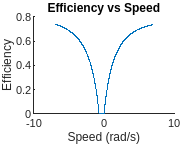


figure;
hold on
plot(Ts, eff);
title('Efficiency vs Speed');
xlabel('Speed (rad/s)');
ylabel('Efficiency');

% axis([min(n) max(n) 0 1]); % Ensuring efficiency is between 0 and 1